close

file=csvread('Mediapipe_world_front.csv',1,0);      %%测量坐标
refFile = csvread('Mediapipe_reference.csv',1,0);  %%参考坐标

[angle1, angle2, angle3, angle4] = inversekinematic(file);   %%测量角度
[ref_ang1, ref_ang2, ref_ang3, ref_ang4] = inversekinematic(refFile);  %%参考坐标

%计算四个角度误差
error1=0;
error2=0;
error3=0;
error4=0;
for i=1:1500   %%可能要改1500
    error1=error1+abs(angle1(i,1)-ref_ang1(i,1)) ;
    error2=error2+abs(angle2(i,1)-ref_ang2(i,1)) ;
    error3=error3+abs(angle3(i,1)-ref_ang3(i,1)) ;
    error4=error4+abs(angle4(i,1)-ref_ang4(i,1)) ;
end
error1=error1/1500

error1 = 39.1588

error2=error2/1500

error2 = 4.8648

error3=error3/1500

error3 = 41.9967

error4=error4/1500

error4 = 7.8052

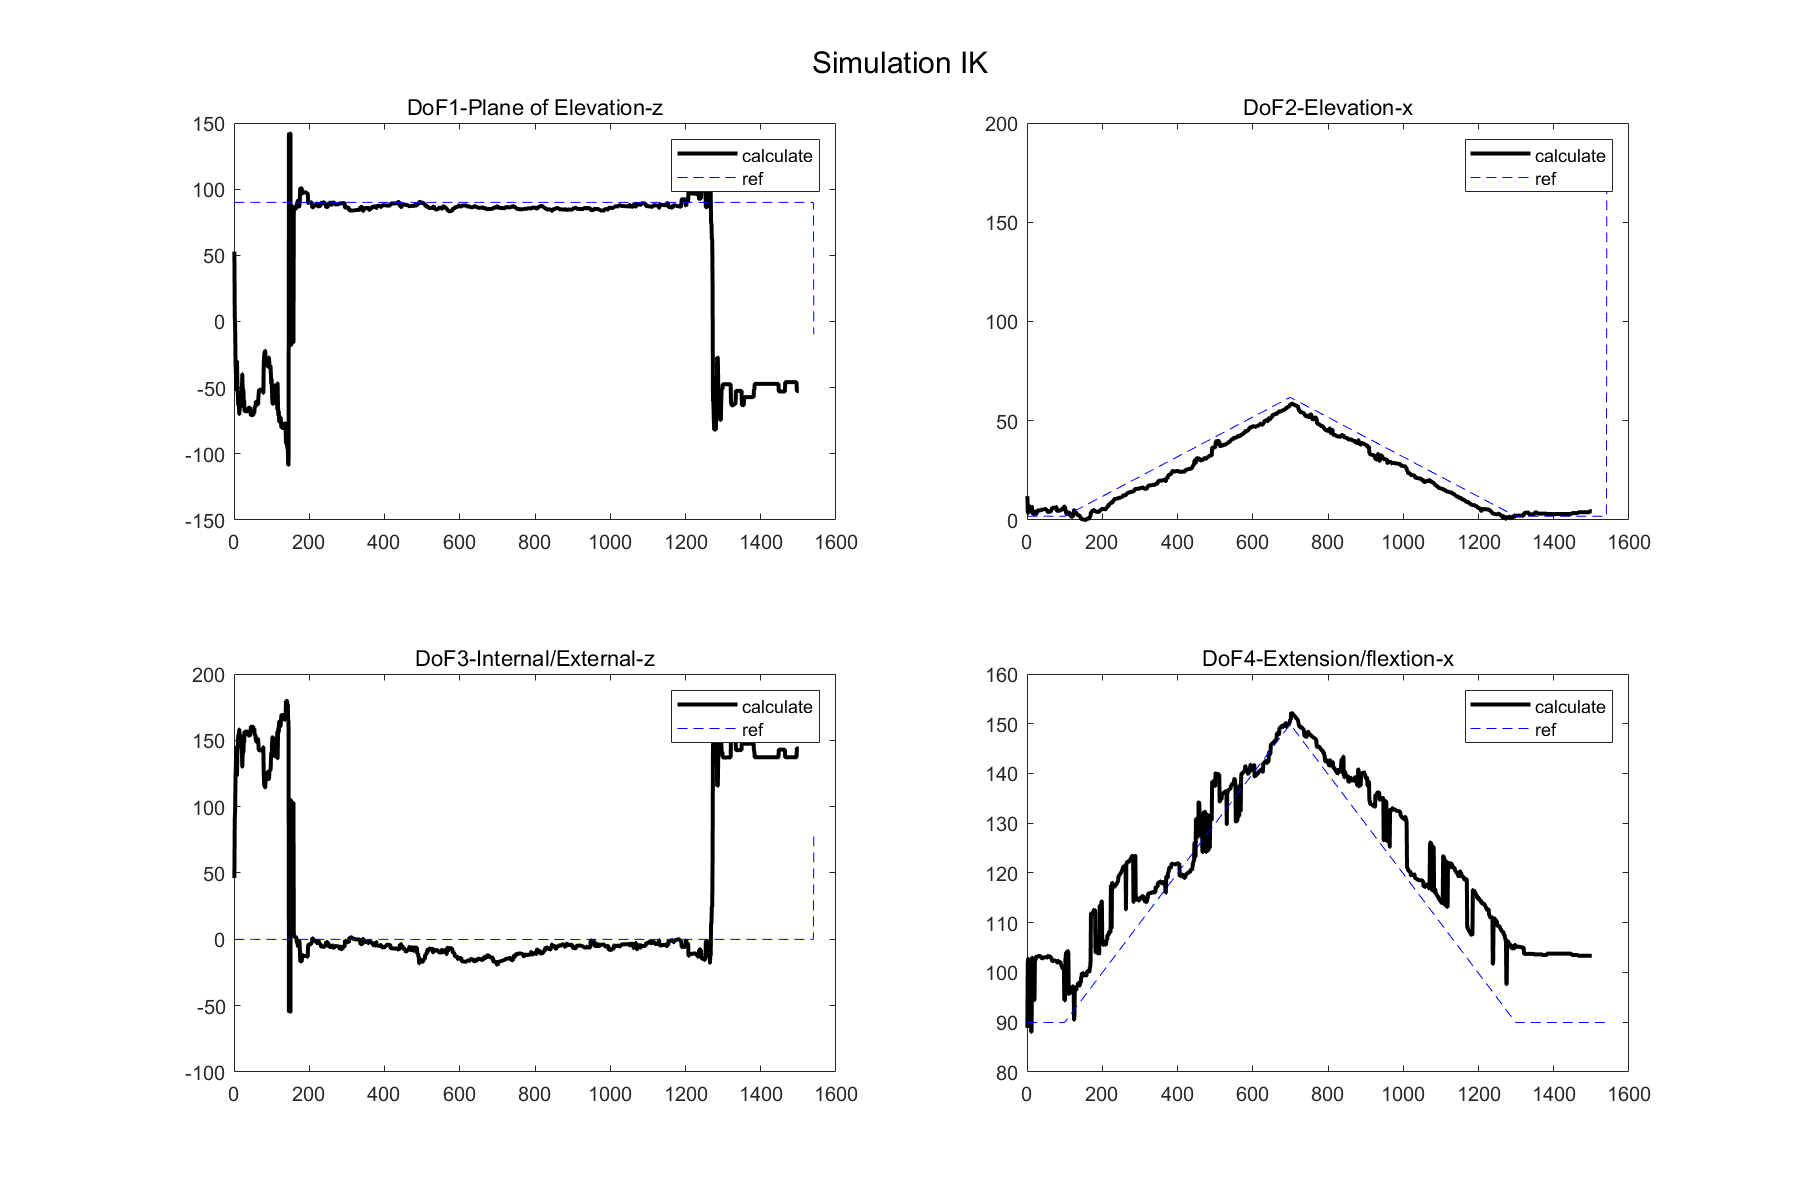


figure
set(gcf,'Position',[10 10 1200 800])
subplot(2,2,1)
plot(angle1(:,1),'k',"LineWidth",2)
hold on
plot(ref_ang1(:,1),'b--')
hold off
% axis([0 2000,-200,200])
title('DoF1-Plane of Elevation-z')
legend('calculate','ref')

subplot(2,2,2)
plot(angle2(:,1),'k',"LineWidth",2)
hold on
plot(ref_ang2(:,1),'b--')
hold off
% axis([0 2000,0,150])
title('DoF2-Elevation-x')
legend('calculate','ref')

subplot(2,2,3)
plot(angle3(:,1),'k',"LineWidth",2)
hold on
plot(ref_ang3(:,1),'b--')
hold off
% axis([0 2000,-100,100])
title('DoF3-Internal/External-z')
legend('calculate','ref')

subplot(2,2,4)
plot(angle4(:,1),'k',"LineWidth",2)
hold on
plot(ref_ang4(:,1),'b--')
hold off
% axis([0 2000,50,200])
title('DoF4-Extension/flextion-x')
legend('calculate','ref')
sgtitle('Simulation IK')

figure
plot(P_se(:,1))
hold on
plot(P_se(:,2))
hold on
plot(P_se(:,3))
hold off
legend('x','y','z')

figure
plot(P_se2(:,1))
hold on
plot(P_se2(:,2))
hold on
plot(P_se2(:,3))
hold off
legend('x','y','z')

figure
plot(P_sw2(:,1))
hold on
plot(P_sw2(:,2))
hold on
plot(P_sw2(:,3))
hold off
legend('x','y','z')

function [angle1,angle2, angle3 ,angle4] = inversekinematic(file)
    
    len=size(file,1);
    angle1=zeros(len,2);
    angle2=zeros(len,1);
    angle3=zeros(len,3);
    angle4=zeros(len,1);
    P_se2=zeros(len,3);
    P_sw2=zeros(len,3);
    
    % 读坐标
    P_hip=[file(:,1),file(:,2),file(:,3)];   %胯骨
    P_ne=[file(:,4),file(:,5),file(:,6)];   %脖子
    P_sh_l=[file(:,7),file(:,8),file(:,9)];  %左肩
    P_shoulder=[file(:,10),file(:,11),file(:,12)];  %右肩
    P_elbow=[file(:,13),file(:,14),file(:,15)];  %肘
    P_wrist=[file(:,16),file(:,17),file(:,18)];     %手腕
    
    
    P_se=-P_shoulder+P_elbow;
    P_sw=P_wrist-P_shoulder;
    P_lr=P_shoulder-P_sh_l;
    B=(P_wrist-P_elbow);
    A=(P_shoulder-P_elbow);
    
    for i=1:size(file,1)
        
    %     计算坐标轴旋转的矩阵
        x_axis=P_lr(i,:)';
        x_axis=x_axis/norm(x_axis);    
        y_axis=cross(x_axis,P_hip(i,:)-P_shoulder(i,:))';
        y_axis=y_axis/norm(y_axis);    
        z_axis=cross(x_axis,y_axis);
        z_axis=z_axis/norm(z_axis);
        TT=[x_axis,y_axis,z_axis];
        
        
        P_se2(i,:)=TT'*P_se(i,:)';
        if abs(P_se2(i,1))< 10e-5
            P_se2(i,1)=0;
        end
        if abs(P_se2(i,2))< 10e-5
            P_se2(i,2)=0;
        end
        if abs(P_se2(i,3))< 10e-5
            P_se2(i,3)=0;
        end
    %     计算角度
        alpha_shoulder = atan2d(P_se2(i,2),P_se2(i,1));
        angle1(i,2)=0;    
        P_sw2(i,:)=TT'*P_sw(i,:)';
        if alpha_shoulder==0
            alpha_shoulder = atan2d(P_sw2(i,2),P_sw2(i,1));
            angle1(i,2)=1;
        end
        angle1(i,1)=alpha_shoulder;
        
        beta_shoulder = atan2d(P_se2(i,3),sqrt(P_se2(i,2)^2+P_se2(i,1)^2))+90; 
        angle2(i,1)=beta_shoulder;
        
        elbow_ang=acosd(dot(A(i,:),B(i,:))/(norm(A(i,:))*norm(B(i,:))));
        angle4(i,1)=elbow_ang;
           
        P_wrist(i,:)=TT'*P_wrist(i,:)';
        P_elbow(i,:)=TT'*P_elbow(i,:)';    
        len_f=norm(B(i,:));   
        P_ew=P_wrist(i,:)-P_elbow(i,:);    
        if beta_shoulder ==0 || elbow_ang==0
            gamma_shoulder=0;
            angle3(i,2)=3;
            angle3(i,1)=0;
            angle3(i,4)=1;
        else
            gamma_shoulder= acosd((cosd(beta_shoulder)*cosd(elbow_ang)-((P_wrist(i,3)-P_elbow(i,3))/len_f))/sind(beta_shoulder)/sind(elbow_ang))-180;
            gamma_shoulder=real(gamma_shoulder);
            angle3(i,1)=gamma_shoulder;
            angle3(i,2)=1;
            ang3=atan2d(P_ew(2),P_ew(1));
            if ang3>angle1(i,1)
                angle3(i,1)=-gamma_shoulder;
                angle3(i,2)=2;
            end
        end
    end
end


